## Input Signal

x =    -0.0305
    0.0305
    0.0305
         0
   -0.0610
   -0.0916
   -0.1221
   -0.0305
    0.0305
   -0.0610


imp =     0.0029
    0.0030
    0.0029
    0.0028
    0.0028
    0.0027
    0.0027
    0.0028
    0.0031
    0.0032


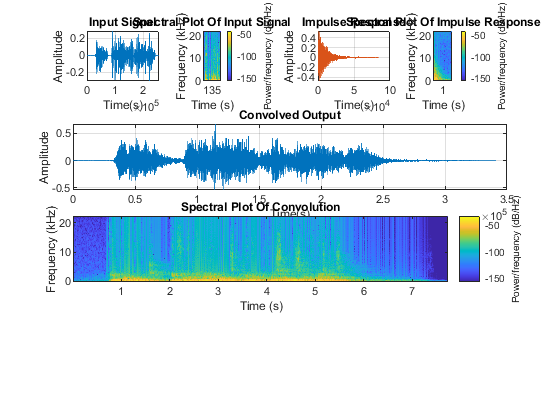

subplot(4,4,1);

%Input signal being loaded into sound card
[x,Fs] = audioread('bospeech_short(2).wav');
%Plot of the Input signal
plot(x)
title('Input Signal')
xlabel('Time(s)')
ylabel('Amplitude')
grid on

subplot(4,4,2)
x=x(:,1)
%Spectogram of the input signal
s_1 = spectrogram(x);
spectrogram(x,128,120,128,Fs,'yaxis')
title('Spectral Plot Of Input Signal')


## Inpulse Response (IR) 

subplot(4,4,3);
%IR being loaded into sound card
[imp,Fsimp]=audioread('Left steps 2.wav');

%plot of the IR
plot(imp)

title('Impulse Response')
xlabel('Time(s)')
ylabel('Amplitude')
grid on

subplot(4,4,4);
imp=imp(:,1)
%Spectogram of IR
s_2= spectrogram(imp);
spectrogram(imp,128,120,128,Fsimp,'yaxis')
title('Spectral Plot Of Impulse Response')


## Output Signal

subplot(4,4,[5,8]);
%Convolution Reverb function
y_out=ConvReverb(x,imp);
%Plot of the Convolved signal 
plot(y_out)
title('Convolved Output')
xlabel('Time(s)')
ylabel('Amplitude')
grid on

subplot(4,4,[9,12])
%Spectogram of Convolved signal
s = spectrogram(y_out);
spectrogram(y_out,128,120,128,Fs,'yaxis')
title('Spectral Plot Of Convolution')


## Output File

filename = 'OutIrReverb.wav';
audiowrite(filename,y_out,Fs);

## Convolution Function

function [y_out]=ConvReverb(x,h,rt60)

%Wet And Dry Gain Controls
d_gain=0.3;
w_gain=0.7;



y_length=length(x)+length(h)-1;
y_pow=pow2(nextpow2(y_length));
%Fast Fourier Transform on the input and the IR
X_fft=fft(x, y_pow);
H_fft=fft(h, y_pow);

%Convolution of the IR and Input signal
Y=X_fft.*H_fft;

%Inverse Fast Fourier Transform to convert from...
%Frequency to time domain
y=real(ifft(Y, y_pow));
y=y(1:1:y_length);

%Normalisation 
y_out=y/max(abs(y));

y_wet =y_out * w_gain;
newX = zeros(size(y_out));
newX(1:size(x,1),1:size(x,2)) = x;
y_out = y_wet + newX *d_gain; 
end







